clc
clear

% Load the Fisher Iris dataset
load fisheriris.mat
X = meas;        % Feature matrix (150 samples x 4 features)
y = (strcmp(species,'setosa'))*1 + (strcmp(species,'versicolor'))*2 + (strcmp(species,'virginica'))*3; % Convert species to numeric labels (1, 2, 3)

% Set the range of cost values to try (logarithmic scale)
cost_values = logspace(-3, 3, 20);

% Initialize an array to store the cross-validation accuracies for each cost
cv_accuracies_ova_rbf = zeros(size(cost_values));
cv_accuracies_ova_poly = zeros(size(cost_values));

% Perform k-fold cross-validation with different cost values
k_fold = 5; % Number of folds for cross-validation
cv = cvpartition(y, 'KFold', k_fold);

for i = 1:length(cost_values)
    cost = cost_values(i);
    accuracies_rbf = zeros(1, k_fold);
    accuracies_poly = zeros(1, k_fold);
    
    for fold = 1:k_fold
        train_idx = training(cv, fold);
        test_idx = test(cv, fold);
        
        X_train = X(train_idx, :);
        y_train = y(train_idx);
        X_test = X(test_idx, :);
        y_test = y(test_idx);
        
        % Train SVM with the radial (RBF) kernel and current cost using OvA
        svm_model_ova_rbf = fitcecoc(X_train, y_train, 'Learners', templateSVM('KernelFunction', 'RBF', 'BoxConstraint', cost));
        
        % Train SVM with the polynomial kernel and current cost using OvA
        svm_model_ova_poly = fitcecoc(X_train, y_train, 'Learners', templateSVM('KernelFunction', 'polynomial', 'BoxConstraint', cost));
        
        % Predict on the test set with RBF kernel
        y_pred_ova_rbf = predict(svm_model_ova_rbf, X_test);
        
        % Predict on the test set with polynomial kernel
        y_pred_ova_poly = predict(svm_model_ova_poly, X_test);
        
        % Compute accuracy for the current fold with RBF kernel
        accuracy_rbf = sum(y_pred_ova_rbf == y_test) / length(y_test);
        accuracies_rbf(fold) = accuracy_rbf;
        
        % Compute accuracy for the current fold with polynomial kernel
        accuracy_poly = sum(y_pred_ova_poly == y_test) / length(y_test);
        accuracies_poly(fold) = accuracy_poly;
    end
    
    % Calculate the average accuracy across all folds for the current cost
    cv_accuracies_ova_rbf(i) = mean(accuracies_rbf);
    cv_accuracies_ova_poly(i) = mean(accuracies_poly);
end

% Find the cost with the highest cross-validation accuracy for both kernels
[best_accuracy_ova_rbf, best_cost_idx_ova_rbf] = max(cv_accuracies_ova_rbf);
best_cost_ova_rbf = cost_values(best_cost_idx_ova_rbf);

[best_accuracy_ova_poly, best_cost_idx_ova_poly] = max(cv_accuracies_ova_poly);
best_cost_ova_poly = cost_values(best_cost_idx_ova_poly);

% Train the final SVM with the radial (RBF) kernel using the best cost and OvA on the entire dataset
final_svm_model_ova_rbf = fitcecoc(X, y, 'Learners', templateSVM('KernelFunction', 'RBF', 'BoxConstraint', best_cost_ova_rbf));

% Train the final SVM with the polynomial kernel using the best cost and OvA on the entire dataset
final_svm_model_ova_poly = fitcecoc(X, y, 'Learners', templateSVM('KernelFunction', 'polynomial', 'BoxConstraint', best_cost_ova_poly));

% Display the results
disp(['Best cost for SVM with RBF Kernel and OvA: ', num2str(best_cost_ova_rbf)]);

Best cost for SVM with RBF Kernel and OvA: 0.33598


disp(['Cross-validation accuracy with best cost and RBF Kernel: ', num2str(best_accuracy_ova_rbf)]);

Cross-validation accuracy with best cost and RBF Kernel: 0.97333



disp(['Best cost for SVM with Polynomial Kernel and OvA: ', num2str(best_cost_ova_poly)]);

Best cost for SVM with Polynomial Kernel and OvA: 0.001


disp(['Cross-validation accuracy with best cost and Polynomial Kernel: ', num2str(best_accuracy_ova_poly)]);

Cross-validation accuracy with best cost and Polynomial Kernel: 0.96


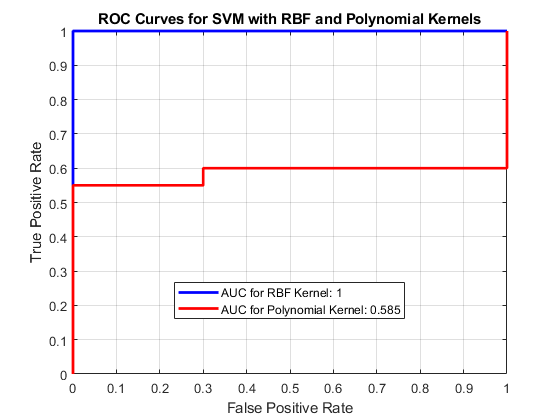


% ROC curves for both SVM models

% Predict probabilities on the test set for RBF kernel
[y_pred_rbf, scores_rbf] = predict(final_svm_model_ova_rbf, X_test);

% Convert the labels to binary for ROC curve analysis (1: Positive, others: Negative)
labels_binary_rbf = y_test;
labels_binary_rbf(labels_binary_rbf ~= 1) = 0;

% Calculate the ROC curve and AUC for RBF kernel
[X_roc_rbf, Y_roc_rbf, ~, AUC_rbf] = perfcurve(labels_binary_rbf, scores_rbf(:, 2), 0);

% Predict probabilities on the test set for Polynomial kernel
[y_pred_poly, scores_poly] = predict(final_svm_model_ova_poly, X_test);

% Convert the labels to binary for ROC curve analysis (1: Positive, others: Negative)
labels_binary_poly = y_test;
labels_binary_poly(labels_binary_poly ~= 1) = 0;

% Calculate the ROC curve and AUC for Polynomial kernel
[X_roc_poly, Y_roc_poly, ~, AUC_poly] = perfcurve(labels_binary_poly, scores_poly(:, 2), 0);

% Plot the ROC curves for both kernels
figure;
plot(X_roc_rbf, Y_roc_rbf, 'b-', 'LineWidth', 2);
hold on;
plot(X_roc_poly, Y_roc_poly, 'r-', 'LineWidth', 2);
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title('ROC Curves for SVM with RBF and Polynomial Kernels');
legend(['AUC for RBF Kernel: ', num2str(AUC_rbf)], ['AUC for Polynomial Kernel: ', num2str(AUC_poly)], 'Location', 'Best');
grid on;
hold off;

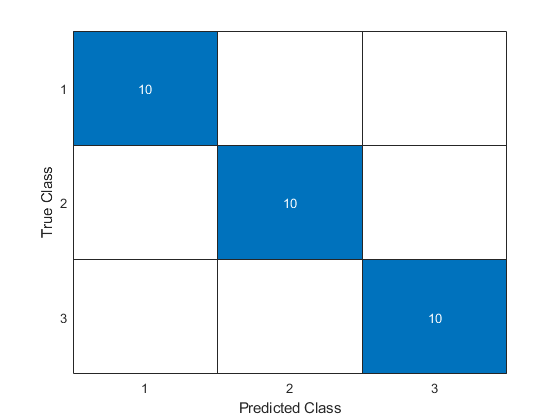


confusionchart(y_test, y_pred_poly)

confusionchart(y_test, y_pred_rbf)